clear, close all, clc


Normal distribution is a bell shaped, symmetrical distributions. It is presented by the letter Z as defined below.


$$Z=\frac{X-\mu }{\sigma }$$
 

X represents a random varible from a normal distribution. Based on that, $\sigma$ represents the standard deviation of the curve, and $\mu$ represents the mean.

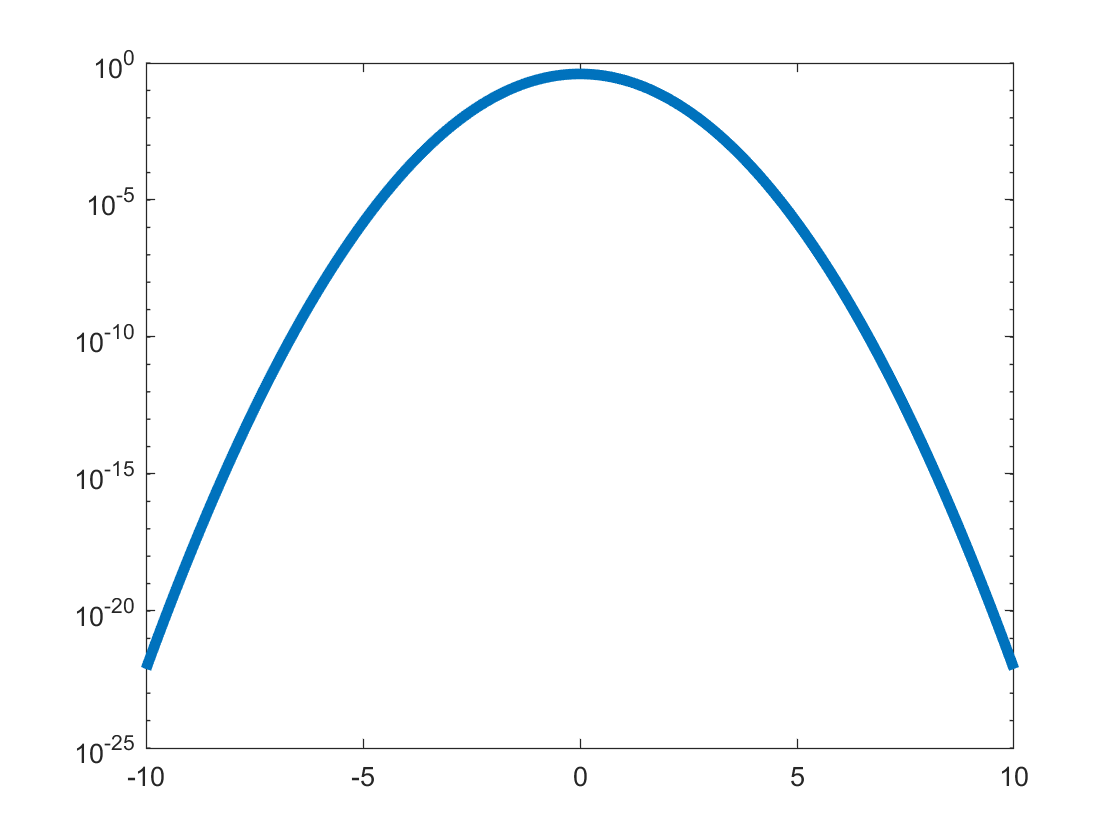

x = linspace(-10,10,1000);
gaus = makedist("Normal",'mu',0,'sigma',1); 
semilogy(x,pdf(gaus,x),"LineWidth",4);

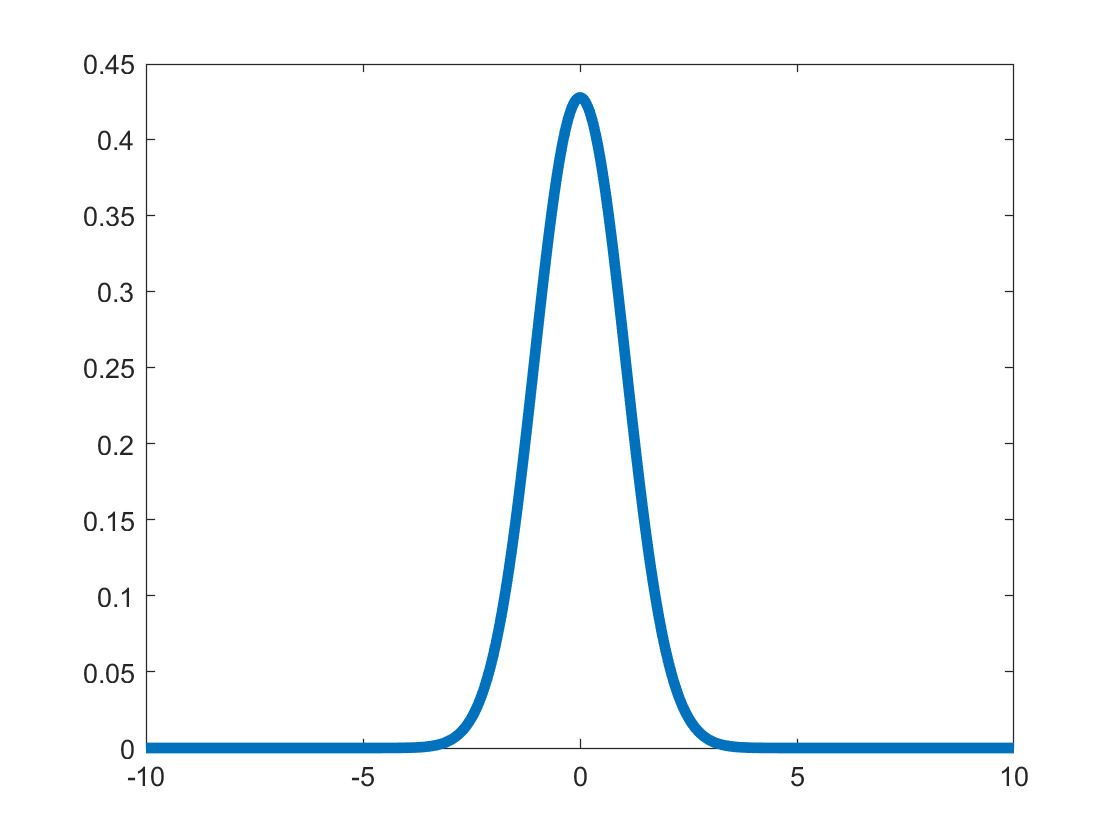


Norm_Int = erf(pdf(gaus,x));
plot(x,Norm_Int, "LineWidth",4)

Here I am using $\phi \left(x\right)=\frac{2}{\sqrt{\pi }}\int_0^x e^{-\frac{t^2 }{2}} \mathrm{dt}$

sig_val = erfinv(pdf(gaus,x));
Sig = -0.4

Sig = -0.4000

PercentWithin_Sig = 1-sig_val(500+50*Sig)

PercentWithin_Sig = 0.6626